load exampleMaps
whos

  Name              Size               Bytes  Class      Attributes

  complexMap       41x52                2132  logical              
  emptyMap         26x27                 702  logical              
  simpleMap        26x27                 702  logical              
  ternaryMap      501x501            2008008  double               



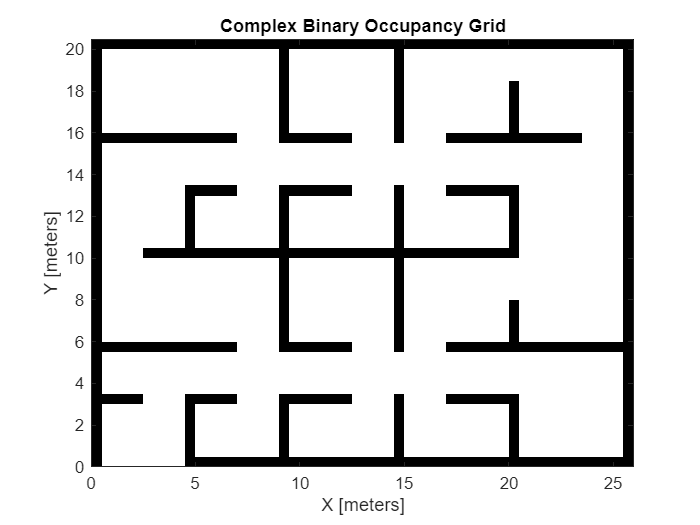


% Step 1: Load built-in complexMap
load exampleMaps

% Create binary occupancy map
map = binaryOccupancyMap(complexMap, 2); % resolution = 2 cells/meter

% Display
figure;
show(map);
title('Complex Binary Occupancy Grid');


% Step 2: Inflate map
robotRadius = 0.5;
mapInflated = copy(map);
inflate(mapInflated, robotRadius);

% Corrected Start and Goal positions
startPose = [2, 2, 0];    % Confirmed free
goalPose  = [24, 18, 0];  % Confirmed free earlier

% Verify
fprintf('Start occupancy (must be 0): %d\n', getOccupancy(mapInflated, [startPose(1), startPose(2)]));

Start occupancy (must be 0): 0


fprintf('Goal occupancy (must be 0): %d\n',  getOccupancy(mapInflated, [goalPose(1),  goalPose(2)]));

Goal occupancy (must be 0): 0


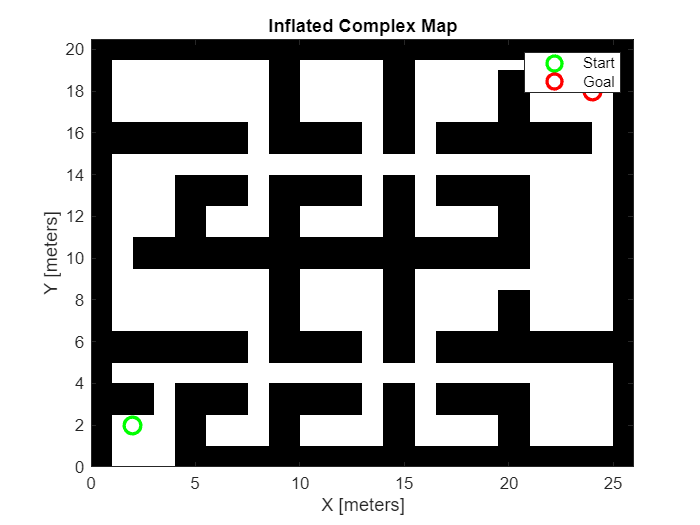


% Display
figure;
show(mapInflated);
title('Inflated Complex Map');
hold on;
plot(startPose(1), startPose(2), 'go', 'MarkerSize', 10, 'LineWidth', 2);
plot(goalPose(1),  goalPose(2),  'ro', 'MarkerSize', 10, 'LineWidth', 2);
legend('Start', 'Goal');
hold off;

Path found! Number of waypoints: 16


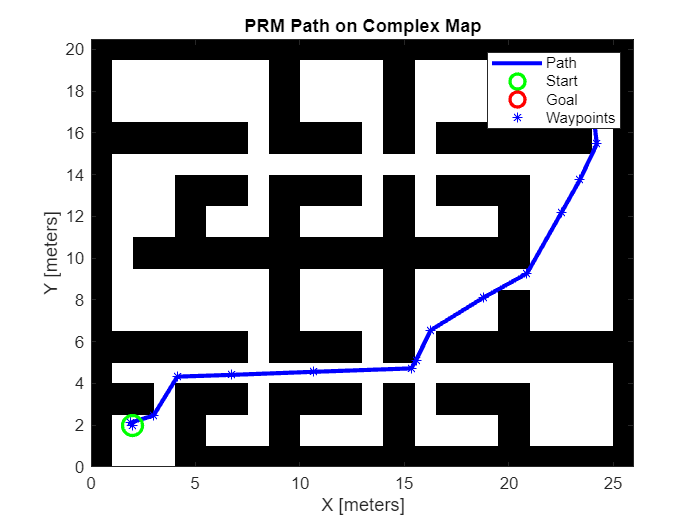


% Step 3: PRM Path Planning
rng(42);

% Create PRM planner
planner = mobileRobotPRM(mapInflated);
planner.NumNodes = 2000;
planner.ConnectionDistance = 5;

% Find path
path = findpath(planner, [startPose(1), startPose(2)], ...
                          [goalPose(1),  goalPose(2)]);

% If not found, retry with higher parameters
if isempty(path)
    disp('Retrying with higher parameters...');
    rng(7);
    planner.NumNodes = 5000;
    planner.ConnectionDistance = 8;
    path = findpath(planner, [startPose(1), startPose(2)], ...
                              [goalPose(1),  goalPose(2)]);
end

if isempty(path)
    disp('No path found.');
else
    fprintf('Path found! Number of waypoints: %d\n', size(path,1));

    % Visualize
    figure;
    show(mapInflated);
    title('PRM Path on Complex Map');
    hold on;
    plot(path(:,1), path(:,2), 'b-',  'LineWidth', 2.5);
    plot(startPose(1), startPose(2), 'go', 'MarkerSize', 12, 'LineWidth', 2);
    plot(goalPose(1),  goalPose(2),  'ro', 'MarkerSize', 12, 'LineWidth', 2);
    plot(path(:,1), path(:,2), 'b*',  'MarkerSize', 6);
    legend('Path', 'Start', 'Goal', 'Waypoints');
    hold off;
end


% Step 4: Smooth Path & Build Waypoint Trajectory

% Add orientation (theta) to each waypoint
numWaypoints = size(path, 1);
theta = zeros(numWaypoints, 1);

% Calculate heading angle between consecutive waypoints
for i = 1:numWaypoints-1
    dx = path(i+1, 1) - path(i, 1);
    dy = path(i+1, 2) - path(i, 2);
    theta(i) = atan2(dy, dx);
end
theta(end) = theta(end-1); % Last point keeps previous heading

% Build full pose trajectory [x, y, theta]
waypoints = [path, theta];

% Display waypoints
disp('Full Waypoint Trajectory [x, y, theta]:');

Full Waypoint Trajectory [x, y, theta]:


disp(waypoints);

    2.0000    2.0000    2.3927
    1.8742    2.1169    0.3054
    2.9938    2.4699    1.0214
    4.1316    4.3281    0.0325
    6.7286    4.4125    0.0373
   10.6427    4.5584    0.0351
   15.3477    4.7235    1.0645
   15.5651    5.1157    1.1162
   16.2669    6.5516    0.5535
   18.7738    8.1007    0.5073
   20.8783    9.2704    1.0557
   22.5186   12.1683    1.0572
   23.4109   13.7500    1.1300
   24.2253   15.4761    1.6897
   23.9420   17.8458    1.2113
   24.0000   18.0000    1.2113




% Time vector - assume robot travels at 0.5 m/s
speeds = zeros(numWaypoints-1, 1);
times  = zeros(numWaypoints, 1);
for i = 1:numWaypoints-1
    dist      = norm(path(i+1,:) - path(i,:));
    speeds(i) = 0.5; % m/s
    times(i+1) = times(i) + dist/speeds(i);
end

fprintf('Total path length: %.2f meters\n',  sum(vecnorm(diff(path),2,2)));

Total path length: 31.75 meters


fprintf('Estimated travel time: %.2f seconds\n', times(end));

Estimated travel time: 63.51 seconds


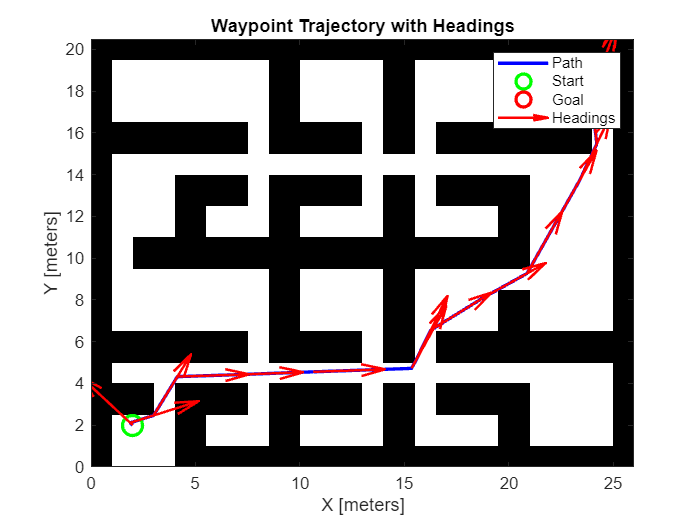


% Visualize smoothed trajectory with headings
figure;
show(mapInflated);
title('Waypoint Trajectory with Headings');
hold on;
plot(path(:,1), path(:,2), 'b-', 'LineWidth', 2);
plot(startPose(1), startPose(2), 'go', 'MarkerSize', 12, 'LineWidth', 2);
plot(goalPose(1),  goalPose(2),  'ro', 'MarkerSize', 12, 'LineWidth', 2);

% Draw heading arrows at each waypoint
quiver(waypoints(:,1), waypoints(:,2), ...
       cos(waypoints(:,3)), sin(waypoints(:,3)), ...
       0.5, 'r', 'LineWidth', 1.5);

legend('Path', 'Start', 'Goal', 'Headings');
hold off;

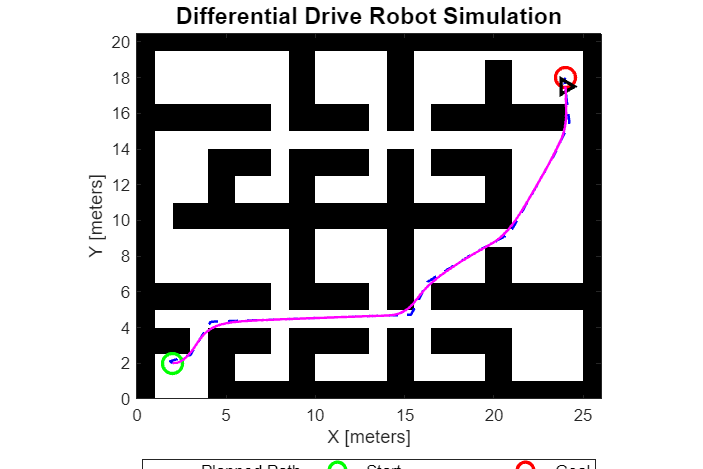


% Step 5 (With Video Recording): Differential Drive Robot Simulation

controller = controllerPurePursuit;
controller.Waypoints = path;
controller.DesiredLinearVelocity = 0.5;
controller.MaxAngularVelocity    = 1.0;
controller.LookaheadDistance     = 1.5;

robotPose  = startPose;
distToGoal = norm(robotPose(1:2) - goalPose(1:2));
goalRadius  = 0.5;
sampleTime  = 0.1;
trajectory  = robotPose;

% Setup figure - wider for legend
fig = figure;
fig.Position = [100, 100, 900, 600]; % [left, bottom, width, height]
show(mapInflated);
title('Differential Drive Robot Simulation', 'FontSize', 14, 'FontWeight', 'bold');
hold on;
plot(path(:,1), path(:,2), 'b--', 'LineWidth', 1.5);
plot(startPose(1), startPose(2), 'go', 'MarkerSize', 12, 'LineWidth', 2);
plot(goalPose(1),  goalPose(2),  'ro', 'MarkerSize', 12, 'LineWidth', 2);
robotPlot = plot(robotPose(1), robotPose(2), 'k>', 'MarkerSize', 8, 'LineWidth', 2);
trajPlot  = plot(robotPose(1), robotPose(2), 'm-', 'LineWidth', 1.5);

% Clean legend - two columns outside bottom
lgd = legend('Planned Path', 'Start', 'Goal', 'Robot', 'Actual Trajectory');
lgd.Location    = 'southoutside';
lgd.Orientation = 'horizontal';
lgd.FontSize    = 10;
lgd.NumColumns  = 3;  % Split into 3 columns - 2 rows

% Adjust subplot to make room for legend
ax = gca;
ax.Position = [0.1, 0.15, 0.85, 0.78]; % [left, bottom, width, height]

% ---- Video Writer Setup ----
videoFile = 'robot_simulation.avi';
v = VideoWriter(videoFile);
v.FrameRate = 10;
open(v);

% Simulation loop
while distToGoal > goalRadius
    [vLin, vAng] = controller(robotPose);

    robotPose(1) = robotPose(1) + vLin * cos(robotPose(3)) * sampleTime;
    robotPose(2) = robotPose(2) + vLin * sin(robotPose(3)) * sampleTime;
    robotPose(3) = robotPose(3) + vAng * sampleTime;

    trajectory = [trajectory; robotPose];

    set(robotPlot, 'XData', robotPose(1), 'YData', robotPose(2));
    set(trajPlot,  'XData', trajectory(:,1), 'YData', trajectory(:,2));

    distToGoal = norm(robotPose(1:2) - goalPose(1:2));

    drawnow limitrate;

    % Capture frame
    frame = getframe(fig);
    writeVideo(v, frame);
end


% Close video writer
close(v);
disp('Robot reached the goal!');

Robot reached the goal!


fprintf('Final robot pose: x=%.2f, y=%.2f, theta=%.2f\n', ...
         robotPose(1), robotPose(2), robotPose(3));

Final robot pose: x=24.01, y=17.51, theta=1.59


fprintf('Video saved as: %s\n', videoFile);

Video saved as: robot_simulation.avi


fprintf('Video location: %s\n', fullfile(pwd, videoFile));

Video location: D:\Matlab\Differential Drive Path Simulation\robot_simulation.avi



% Step 6: Final Results & Analysis

% Calculate actual trajectory length
actualLength = sum(vecnorm(diff(trajectory(:,1:2)), 2, 2));
fprintf('Planned path length:   %.2f meters\n', sum(vecnorm(diff(path),2,2)));

Planned path length:   31.75 meters


fprintf('Actual travel length:  %.2f meters\n', actualLength);

Actual travel length:  30.25 meters


fprintf('Total time simulated:  %.2f seconds\n', size(trajectory,1) * sampleTime);

Total time simulated:  60.60 seconds


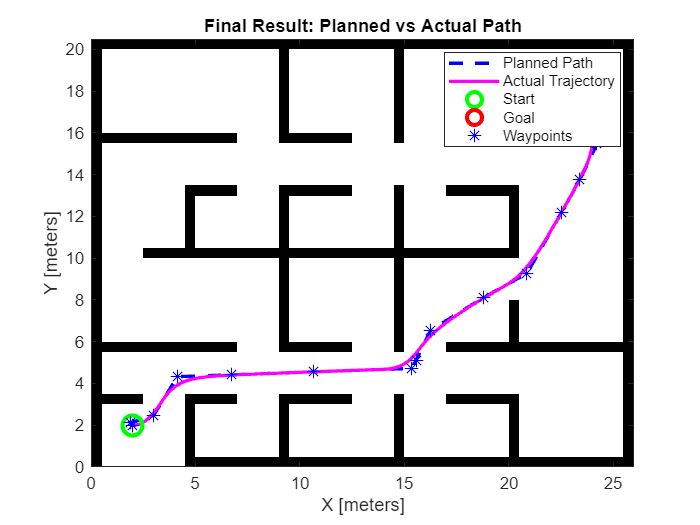


% Final plot - overlay everything
figure;
show(map);   % Show original uninflated map
title('Final Result: Planned vs Actual Path');
hold on;

% Planned path
plot(path(:,1), path(:,2), 'b--', 'LineWidth', 2);

% Actual trajectory
plot(trajectory(:,1), trajectory(:,2), 'm-', 'LineWidth', 2);

% Start and Goal
plot(startPose(1), startPose(2), 'go', 'MarkerSize', 12, 'LineWidth', 2.5);
plot(goalPose(1),  goalPose(2),  'ro', 'MarkerSize', 12, 'LineWidth', 2.5);

% Waypoints
plot(path(:,1), path(:,2), 'b*', 'MarkerSize', 8);

legend('Planned Path', 'Actual Trajectory', 'Start', 'Goal', 'Waypoints');
hold off;


% Step 7: Final Results & Analysis

% Calculate metrics
plannedLength = sum(vecnorm(diff(path), 2, 2));
actualLength  = sum(vecnorm(diff(trajectory(:,1:2)), 2, 2));
totalTime     = size(trajectory, 1) * sampleTime;
efficiency    = (plannedLength / actualLength) * 100;

% Print analysis
fprintf('============ FINAL ANALYSIS ============\n');

============ FINAL ANALYSIS ============


fprintf('Planned path length:    %.2f meters\n',  plannedLength);

Planned path length:    31.75 meters


fprintf('Actual travel length:   %.2f meters\n',  actualLength);

Actual travel length:   30.25 meters


fprintf('Total time simulated:   %.2f seconds\n', totalTime);

Total time simulated:   60.60 seconds


fprintf('Average speed:          %.2f m/s\n',     actualLength/totalTime);

Average speed:          0.50 m/s


fprintf('Path efficiency:        %.1f%%\n',        efficiency);

Path efficiency:        105.0%


fprintf('Goal position:          [%.1f, %.1f]\n',  goalPose(1), goalPose(2));

Goal position:          [24.0, 18.0]


fprintf('Final robot position:   [%.2f, %.2f]\n', robotPose(1), robotPose(2));

Final robot position:   [24.01, 17.51]


fprintf('Position error:         %.2f meters\n',  norm(robotPose(1:2) - goalPose(1:2)));

Position error:         0.49 meters


fprintf('========================================\n');

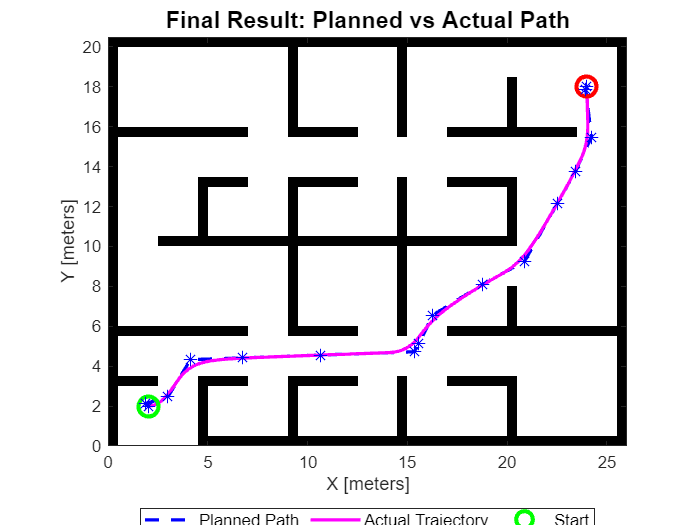


% ---- Plot 1: Final Planned vs Actual Path ----
figure;
show(map);   % Original uninflated map
title('Final Result: Planned vs Actual Path', 'FontSize', 14, 'FontWeight', 'bold');
hold on;
plot(path(:,1),        path(:,2),        'b--', 'LineWidth', 2);
plot(trajectory(:,1),  trajectory(:,2),  'm-',  'LineWidth', 2);
plot(startPose(1), startPose(2), 'go', 'MarkerSize', 12, 'LineWidth', 2.5);
plot(goalPose(1),  goalPose(2),  'ro', 'MarkerSize', 12, 'LineWidth', 2.5);
plot(path(:,1), path(:,2), 'b*', 'MarkerSize', 8);
lgd = legend('Planned Path', 'Actual Trajectory', 'Start', 'Goal', 'Waypoints');
lgd.Location    = 'southoutside';
lgd.Orientation = 'horizontal';
lgd.NumColumns  = 3;
lgd.FontSize    = 10;
ax = gca;
ax.Position = [0.1, 0.15, 0.85, 0.78];
hold off;

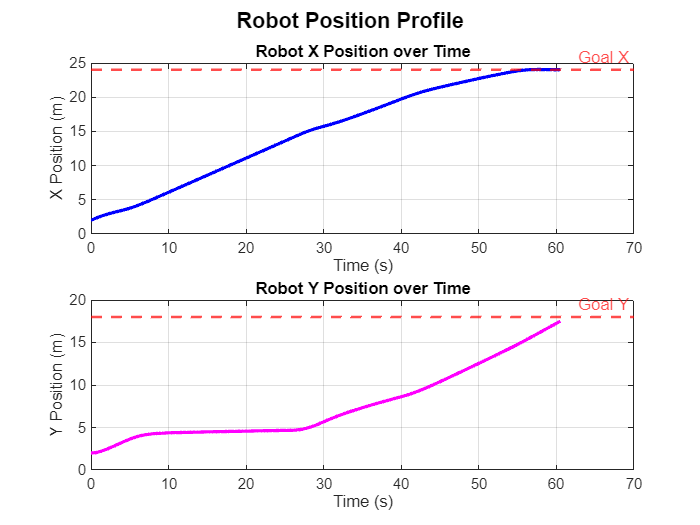


% ---- Plot 2: X and Y position over time ----
timeVec = (0:size(trajectory,1)-1) * sampleTime;
figure;
subplot(2,1,1);
plot(timeVec, trajectory(:,1), 'b-', 'LineWidth', 2);
yline(goalPose(1), 'r--', 'Goal X', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('X Position (m)');
title('Robot X Position over Time');
grid on;

subplot(2,1,2);
plot(timeVec, trajectory(:,2), 'm-', 'LineWidth', 2);
yline(goalPose(2), 'r--', 'Goal Y', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Y Position (m)');
title('Robot Y Position over Time');
grid on;
sgtitle('Robot Position Profile', 'FontSize', 13, 'FontWeight', 'bold');

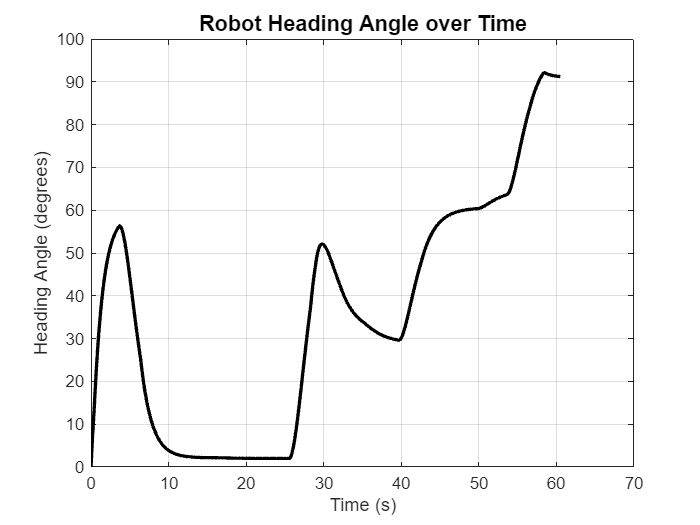


% ---- Plot 3: Heading angle over time ----
figure;
plot(timeVec, rad2deg(trajectory(:,3)), 'k-', 'LineWidth', 2);
xlabel('Time (s)'); ylabel('Heading Angle (degrees)');
title('Robot Heading Angle over Time', 'FontSize', 13, 'FontWeight', 'bold');
grid on;

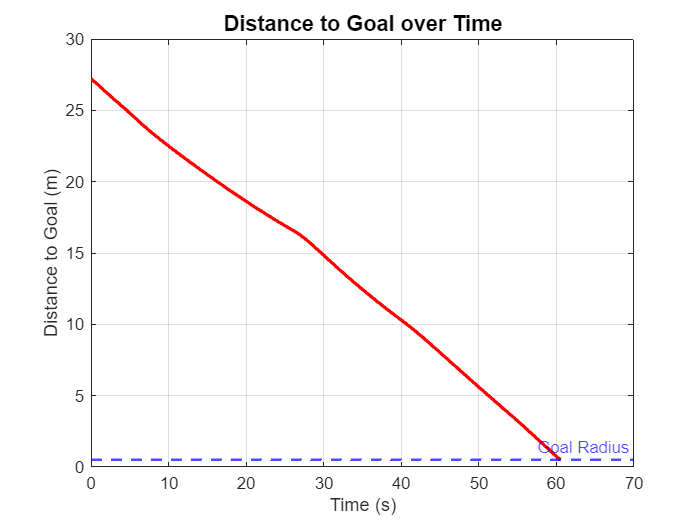


% ---- Plot 4: Distance to goal over time ----
distOverTime = vecnorm(trajectory(:,1:2) - goalPose(1:2), 2, 2);
figure;
plot(timeVec, distOverTime, 'r-', 'LineWidth', 2);
yline(0.5, 'b--', 'Goal Radius', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Distance to Goal (m)');
title('Distance to Goal over Time', 'FontSize', 13, 'FontWeight', 'bold');
grid on;


% Clear conflicting variable names first
clear plannerRRT plannerRRTStar ss ss2 sv sv2

% ---- RRT (Rerun with fixed names) ----
rng(42);

ssRRT = stateSpaceSE2;
ssRRT.StateBounds = [map.XWorldLimits; map.YWorldLimits; [-pi, pi]];

svRRT = validatorOccupancyMap(ssRRT);
svRRT.Map = mapInflated;
svRRT.ValidationDistance = 0.1;

pRRT = plannerRRT(ssRRT, svRRT);
pRRT.MaxIterations         = 10000;
pRRT.MaxConnectionDistance = 2;

startState = [startPose(1), startPose(2), startPose(3)];
goalState  = [goalPose(1),  goalPose(2),  goalPose(3)];

[pathRRT, infoRRT] = plan(pRRT, startState, goalState);

if infoRRT.IsPathFound
    fprintf('RRT Path found!\n');
    fprintf('RRT Waypoints:   %d\n', size(pathRRT.States,1));
    fprintf('RRT Path length: %.2f meters\n', ...
             sum(vecnorm(diff(pathRRT.States(:,1:2)),2,2)));
end

RRT Path found!


RRT Waypoints:   21


RRT Path length: 36.15 meters


RRT* Path found!


RRT* Waypoints:   24


RRT* Path length: 33.91 meters


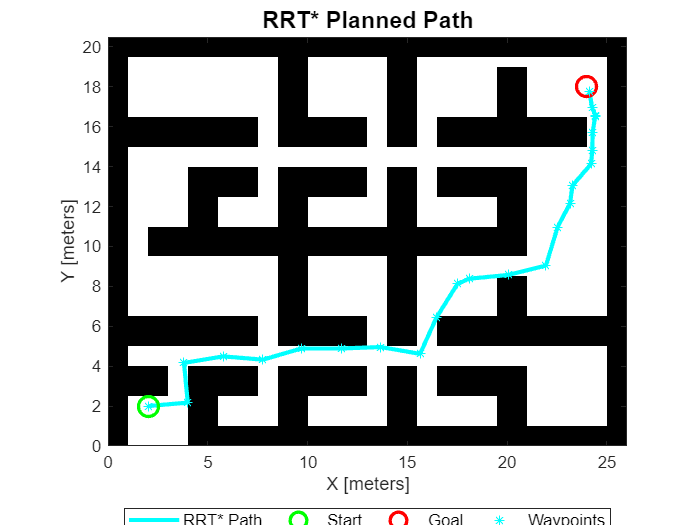


% ---- RRT* ----
rng(42);

ssRRTS = stateSpaceSE2;
ssRRTS.StateBounds = [map.XWorldLimits; map.YWorldLimits; [-pi, pi]];

svRRTS = validatorOccupancyMap(ssRRTS);
svRRTS.Map = mapInflated;
svRRTS.ValidationDistance = 0.1;

pRRTS = plannerRRTStar(ssRRTS, svRRTS);
pRRTS.MaxIterations              = 10000;
pRRTS.MaxConnectionDistance      = 2;
pRRTS.ContinueAfterGoalReached   = true;

[pathRRTS, infoRRTS] = plan(pRRTS, startState, goalState);

if infoRRTS.IsPathFound
    fprintf('RRT* Path found!\n');
    fprintf('RRT* Waypoints:   %d\n', size(pathRRTS.States,1));
    fprintf('RRT* Path length: %.2f meters\n', ...
             sum(vecnorm(diff(pathRRTS.States(:,1:2)),2,2)));

    % Visualize RRT*
    figure;
    show(mapInflated);
    title('RRT* Planned Path', 'FontSize', 14, 'FontWeight', 'bold');
    hold on;
    plot(pathRRTS.States(:,1), pathRRTS.States(:,2), 'c-', 'LineWidth', 2.5);
    plot(startPose(1), startPose(2), 'go', 'MarkerSize', 12, 'LineWidth', 2);
    plot(goalPose(1),  goalPose(2),  'ro', 'MarkerSize', 12, 'LineWidth', 2);
    plot(pathRRTS.States(:,1), pathRRTS.States(:,2), 'c*', 'MarkerSize', 6);
    lgd = legend('RRT* Path', 'Start', 'Goal', 'Waypoints');
    lgd.Location    = 'southoutside';
    lgd.Orientation = 'horizontal';
    lgd.FontSize    = 10;
    ax = gca;
    ax.Position = [0.1, 0.15, 0.85, 0.78];
    hold off;
else
    disp('RRT* could not find path.');
end